# MHB for delays

### Settings

clear vars; close all; clc
format long
global A B C G P Az fre nn gamma x_eq W tau

%% Network settings
nn = 3;           % number of ring cells
flag = 2;         % 0 - regular ring, 1 - NONregular network, 2 - directed network

%% Parameter settings
mp_gamma = 1.1;   % multiplicator of parameter gamma
mp_tau = 1.0;     % multiplicator of parameter tau

%% Simulation settings 
ifi = 0;          % initial phase (if needed)
tend = 1000;      % simulation time 

%% MHB settings
Beta = 3;         % feasible region for amplitudes and offset
NumOfStP = 10;    % Amount of initial points for optimization

### Network Structure

Setting up network stucture

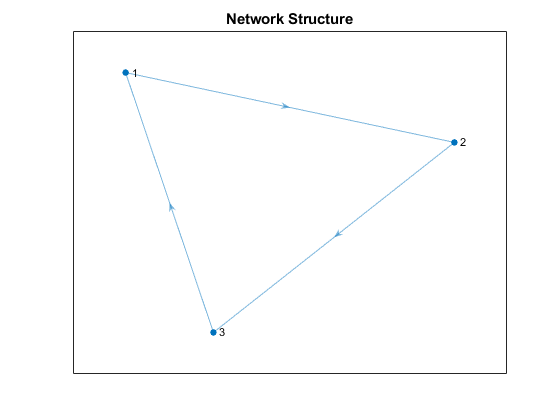

[G,n,offset] = NetworkStructure(nn,flag);

In=eye(n);

### Individual dynamics

%% FitzHuhg-Nagumo model
    
b = 0.08;   

A = [-0.8*b b; -1 1];
B = [0; 1];
C = [0 1];
P = [0; -0.559];


### Equilibrium point(s) and Linearizaton

syms x1 x2 z1 z2 s zu
assume (x1, 'real')
assume (x2, 'real')
assume (z1, 'real')
assume (z2, 'real')

x = [x1;x2];
z = [z1;z2];
J(x) = jacobian(A*x + P + B*C*(-1/3)*x.^3);
eqp = solve((A*x + P + B*C*(-1/3)*x.^3==0),x);

x_eq = [double(eqp.x1); double(eqp.x2)]; % equilibrium point

J0 = double(J(eqp.x1, eqp.x2));          % Jacobian matrix 
huzwitzCrit(J0)                          % Stability check

System is Stable


### Change of coordinates to zero equlibria

Az = [-0.8*b b; -1 (1-x_eq(2)^2)];

J1(z)=jacobian(Az*z + B*C*((-1/3)*z.^3 - x_eq(2)*z.^2));
eqp1 = solve((Az*z + B*C*((-1/3)*z.^3 - x_eq(2)*z.^2)==0),z);
z_eq = [double(eqp1.z1); double(eqp1.z2)];
J01 = double(J1(eqp1.z1, eqp1.z2));
huzwitzCrit(J01)

System is Stable


### Bifurcation point(s)

H(s) = C*((s*eye(length(J01)) - J01)^-1)*B;
H(s) = simplify(H(s));

w = 0:0.0001:1;

L = double(H(1i*w'));

[nu,i] = min(real(L));

om_star = w(i);
disp(['Omega*: ',num2str(om_star)])

Omega*: 0.4202



gamma_min = -1/(2*nu);
disp(['Minimum coupling strength: ',num2str(gamma_min)])

Minimum coupling strength: 2.5376



BC = B*C;

AA = kron(In,(J01-gamma_min*BC));
BB = kron(gamma_min*G,BC);

eq1 = det(kronsum((AA + BB*zu),(AA'+ BB'*(1/zu))));
crit1 = double(solve(eq1==0,zu));
crit1m=[];
f1=[];
for i = 1:length(crit1)
    ei = eig(AA + BB*crit1(i));
    for ii = 1:length(ei)
        if abs(real(ei(ii)))<10e-6 && imag(ei(ii))>0 
            crit1m = [crit1m; crit1(i)];
            f1 = [f1; imag(ei(ii))];
        end
    end   
end

taus = sort((-1i*log(1./crit1m))./f1);
disp(['Critical time-delays for computed minimal coupling strength:'])

Critical time-delays for computed minimal coupling strength:


taus = real(taus(taus>0)) % critical time-delays for computed gamma_min

taus =    4.764392115268577
   4.764397338560347


### Most rigth eigenvalue of linearization

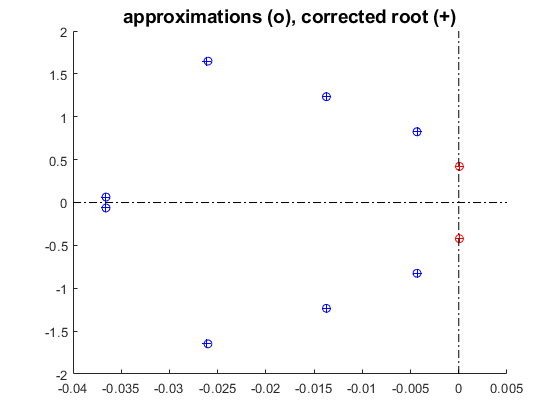


addpath('files_roots')  

gamma =mp_gamma*gamma_min; 
tau = mp_tau*taus(1);

A0 = kron(In,(J01 - gamma*B*C));
A1 = kron(gamma*G,B*C);
hA = [0, tau];

tds = tds_create({A0, A1}, hA);
tds_check_valid(tds)
options=tdsrootsoptions;
options.minimal_real_part= -0.04;
[eigenvalues, N, size_eigenvalue_problem]=tds_charateristic_roots(tds, options);
figure
eigenplot(eigenvalues)

eigenvalues.l1;
eigenvalues.l0;

ur = 0;
sum_ = 0;

for ur = 1:length(eigenvalues.l0)
   if real(eigenvalues.l0(ur))>10e-9
       sum_ = sum_ + 1;
   end
end
disp(['Amount of expected (!!!) stable oscillatory modes: ',num2str(sum_/2)])

Amount of expected (!!!) stable oscillatory modes: 1


### DDE Simulation Zero equlibria

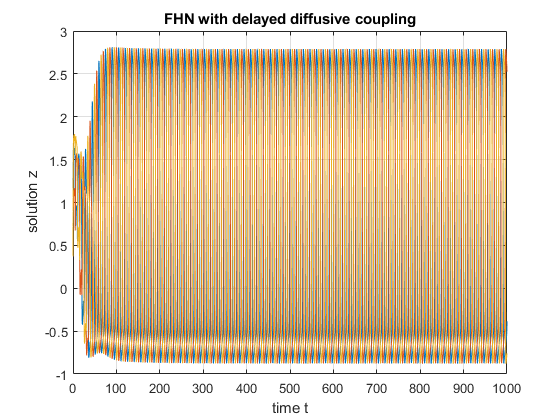


tic

options = ddeset('RelTol',1e-3);
sol = dde23(@FHM_zeroeq,tau,@ddex1hist,[0, tend],options);

dde_z = kron(eye(n),C)*sol.y;
dde_zs = dde_z + fliplr(offset)';
time = sol.x;

figure;
plot(time,dde_z)
title('FHN with delayed diffusive coupling');
xlabel('time t');
ylabel('solution z');
grid on


toc

Elapsed time is 9.833776 seconds.


### Describing function and MHB


%% Transfer function for LTI part
syms W s 
W(s) = C*((s*eye(length(Az)) - Az)^-1)*B;
W(s) = simplify(W(s));


%% Intitial Conditions
g0 = randn(3*nn+1,1);  % shifted
fre = abs(imag(eigenvalues.l1(1)));

tic

rpts = RandomStartPointSet('NumStartPoints',NumOfStP);

[lbound,ubound] = boundsconst(g0,om_star,Beta);
ms = MultiStart('Display','iter','FunctionTolerance',1e-15,'XTolerance',1e-15);

opts = optimoptions(@fmincon,'Algorithm','interior-point','MaxFunctionEvaluations',3500,'StepTolerance',1e-10);
problem = createOptimProblem('fmincon','x0',g0,...
    'objective',@FHNcostfun_shifted,'lb',lbound,'ub',ubound,...
    'options',opts);


[xmin,fmin,flag,outpt,allmins] = run(ms,problem,rpts);


    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         1    4.328e-07       106      1198     4.309e-07
       2         2    7.158e-13        58       690     2.001e-06
       3         1    4.372e-07       102      1160     2.997e-07
       4         1    7.057e-13        54       647         4e-07
       5         1    7.062e-13        67       784         4e-07
       6         1    4.327e-07        95      1082     4.076e-07
       7         1    6.126e-13        53       622     5.083e-07
       8         1    7.643e-13        66       774      7.12e-07
       9         1    7.035e-13        59       687         4e-07
      10         1    7.668e-13        57       669     1.521e-07

MultiStart completed the runs from all start points.

All 10 local solver runs converged with a positive local solver exit flag.



toc

Elapsed time is 2.911398 seconds.


### Reading solution

GG = [allmins.X];
g = GG(:,1);

[g,q,omega,amp,fi,b] = ReadSolution_shifted(g,length(g));

Frequency is equal to 0.4218
Period is equal to 14.8962
DC is 
   0.707126172414087
   0.707126175328058
   0.707126169329253

Amplitudes are equal to 
   1.883554884765099
   1.883554885821473
   1.883554881334063

The phase shift is (RAD)
                   0
   2.094395062500263
   4.188790152796638

The phase shift is (DEG)
   1.0e+02 *

                   0
   1.199999977143033
   2.399999970212066



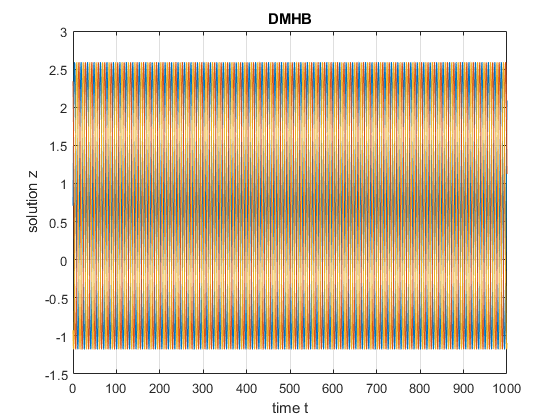


%% Oscillations

[tiq,qsim] = Oscillations_shifted(amp,b,omega,ifi,fi,offset-offset,tend);

figure;
plot(tiq,qsim)
title('DMHB');
xlabel('time t');
ylabel('solution z');
grid on